scores = [];
for i=1: length(h_aminoacid)
    scores = [scores; i,nwalign(char(h_aminoacid(i,1)), char(aminoacid(1,1)), 'scoringmatrix','blosum30','gapopen',5,'extendgap',5)];
end
scores

scores =     1.0000  399.0000
    2.0000   10.4000
    3.0000  -86.4000
    4.0000    5.4000
    5.0000    0.6000
    6.0000   47.0000
    7.0000   55.4000
    8.0000  -10.8000
    9.0000   39.2000
   10.0000  -69.2000


tobetested = find(scores(:,2) > 50)

tobetested =      1
     7


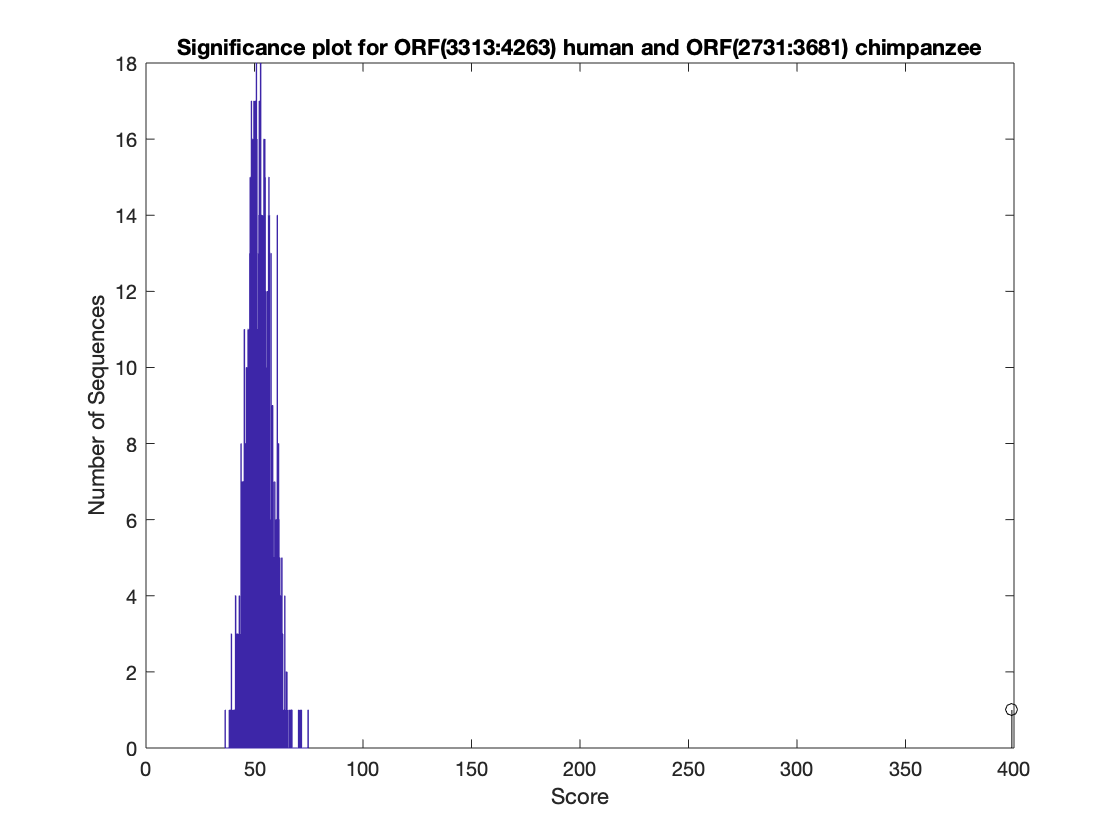

p_value = 0

score = 399

titleStr = "Significance plot for ORF(3313:4263) human and ORF(2731:3681) chimpanzee"

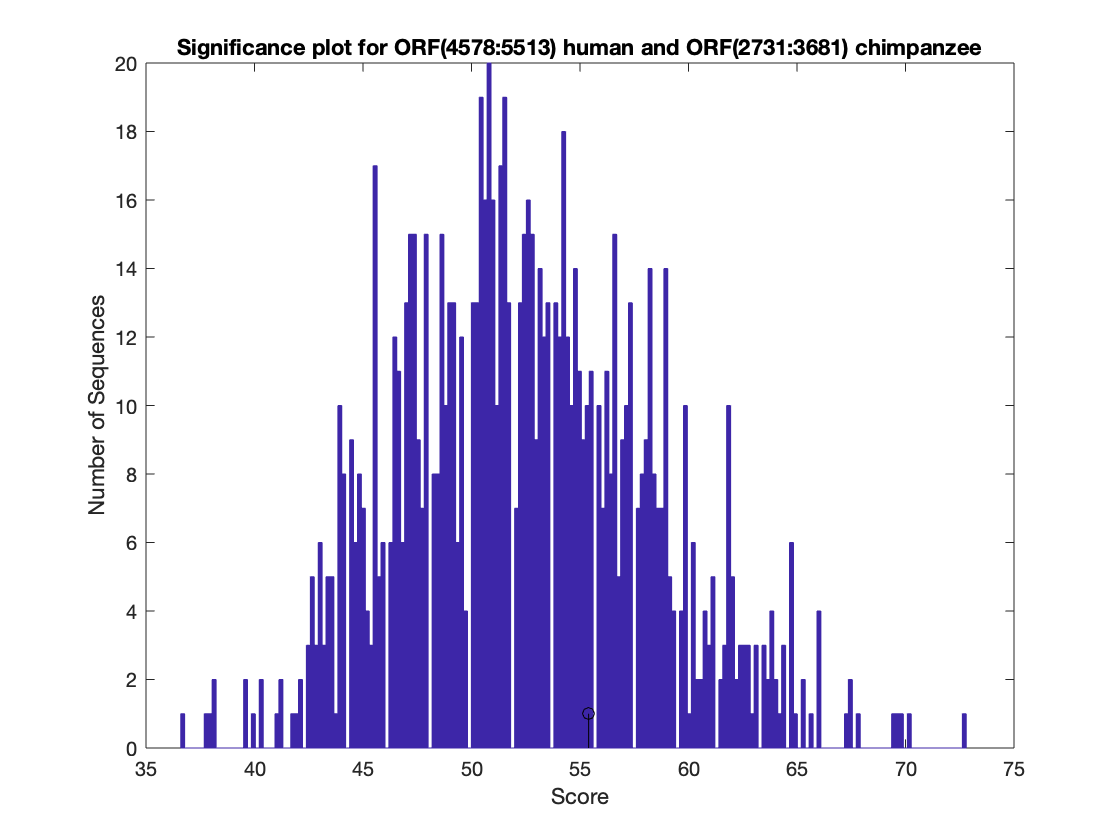

p_value = 0.3020

score = 55.4000

titleStr = "Significance plot for ORF(4578:5513) human and ORF(2731:3681) chimpanzee"

for i=1:length(tobetested)
    h = scores(tobetested(i),1);
    c = 1;
    score = scores(tobetested(i),2);
    human_protein = char(h_aminoacid(h,1));
    chimp_protein = char(aminoacid(c,1));
    n = 1000;
    globalscores = zeros(n,1);
    chimpLen = length(chimp_protein);
    for j = 1:n
        perm = randperm(chimpLen);
        globalscores(j) = nwalign(human_protein,chimp_protein(perm),'scoringmatrix','blosum30','gapopen',5,'extendgap',5);
    end
    figure
    buckets = ceil(n/5);
    hist(globalscores,buckets)
    hold on;
    stem(score,1,'k')
    xlabel('Score'); ylabel('Number of Sequences');
    titleStr = strcat('Significance plot for ORF(' ,h_aminoacid(h,2),':',h_aminoacid(h,3), ...
        ') human and ORF(',aminoacid(1,2),':',aminoacid(1,3), ') chimpanzee');
    title(titleStr);
    hold off;
    p_value = length(find(globalscores >= score)) / 1000
    score
    titleStr
end